# Map Estimation

## 1. Load data

clear all; warning off
% load('./data/dc_corr.mat'); 
% load('./data/sunrisesunset.mat')
% load('./data/Rain_grid.mat','TCRW');
load('./data/Density_inference.mat'); 
addpath('./functions/'); 
load coastlines.mat
Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );

## 2. Initialization of the grid

g.lat=(43:.25:55)';
g.lon=(-5:.25:16)';
g.time = (datetime((data.day(1)-.5):1/24/4:(data.day(end)+0.5),'ConvertFrom','datenum'))';
tmp = dateshift(g.time,'start','day','nearest');
tmp(1)=tmp(2); % change the day assosiated with 13-Feb-2018 00:00 (not used anyway) to 14-Feb-2018 for convinence when computing sunset. 
[g.day_id,g.day]=findgroups(tmp);
% figure; plot(g.time,g.day(g.day_id))

g.nlat=numel(g.lat);
g.nlon=numel(g.lon);
g.nl=numel(g.lat)*numel(g.lon);
g.nt=numel(g.time);
g.nat=numel(g.day);

[g.lat2D, g.lon2D] = ndgrid(g.lat,g.lon);
%[g.lat3D,g.lon3D,g.time3D]=ndgrid(g.lat,g.lon,g.time);

## 3. Mask

Mask onver continental Europe. Select only the Eurasian polyline in coastlat.

tmp = find(isnan(coastlat));
[~,id]=max(diff(tmp));
% plot(coastlat(tmp(id):tmp(id+1)),coastlon(tmp(id):tmp(id+1)))
g_mask_water = inpolygon(g.lat2D,g.lon2D,coastlat(tmp(id):tmp(id+1)),coastlon(tmp(id):tmp(id+1)));
g_mask_water(g.lat2D>52 & g.lat2D<53 & g.lon2D>5 & g.lon2D<7) = true;% Keep the dutch sea
g_mask_water(17,13)=true;
g_mask_water(24,15)=true;
g_mask_water(46,75)=true;
g_mask_water(45,65:66)=true;

Mask distance

Ddist = pdist2([data.lat data.lon], [g.lat2D(:) g.lon2D(:)], @lldistkm);
g_mask_distrad = reshape(min(Ddist)<150,size(g.lat2D));
g_mask_distrad(g.lat2D>50 & g.lon2D<10)=true; % Keep area between netherland and Germany
g_mask_distrad(46,75)=true;
g_mask_distrad(36,84)=true;
g_mask_distrad(16,57:59)=true;
g_mask_distrad(5,39)=true;
g_mask_distrad(13,47)=true;
g_mask_distrad(7,42)=false;

Mask North of spain

% g_mask_spain = g.lat2D>g.lat(2) | g.lon2D>g.lon(14);

Mask Alpes and Italy

[DEM,GeoCellRef] = geotiffread('data/gt30w020n90');
DEM=flipud(double(DEM));
DEM(DEM<-1000)=nan;
F = griddedInterpolant({linspace(GeoCellRef.LatitudeLimits(1), GeoCellRef.LatitudeLimits(end), GeoCellRef.RasterSize(1))',linspace(GeoCellRef.LongitudeLimits(1), GeoCellRef.LongitudeLimits(end), GeoCellRef.RasterSize(2))'}, DEM,'pchip');
g_DEM = F({g.lat, g.lon});

g.mask_maxalt=2000;
g_mask_alt = g_DEM<g.mask_maxalt;
% figure; imagesc(g_mask_alt);

g_mask_alt(end/2:end,:)=true; g_mask_alt(:,1:end/2)=true;
g_mask_alt = cumsum(g_mask_alt,'reverse')>=repmat((g.nlat:-1:1)',1,g.nlon);
g_mask_alt = cumsum(g_mask_alt,2)>=repmat(1:g.nlon,g.nlat,1);
% figure; imagesc(g_mask_alt);

Mask Camargue

% x=[3.75 1;6 1]\[43.25;45];
% g_mask_camargue = ~(g.lon2D.*x(1)+x(2)>g.lat2D & g.lon2D<6);

Combined spatial mask s

g.latlonmask = (g_mask_water & g_mask_distrad & g_mask_alt); %  & g_mask_spain & 
g.nlm = sum(g.latlonmask(:));

Figure

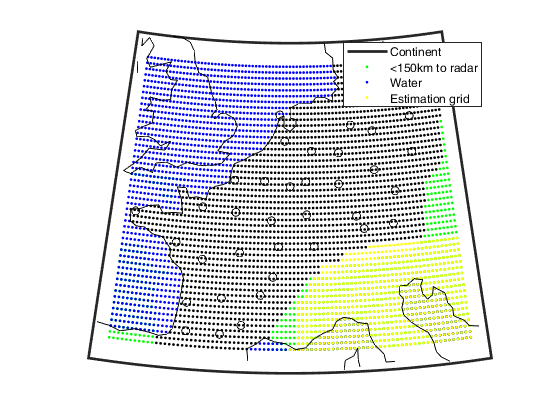

figure; hold on; 
h=worldmap([min([g.lat]-1) max([g.lat]+1)], [min([g.lon]-1) max([g.lon]+1)]); 
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
plotm(g.lat2D(~g_mask_distrad),g.lon2D(~g_mask_distrad),'.g')
plotm(g.lat2D(~g_mask_water),g.lon2D(~g_mask_water),'.b')
% plotm(g.lat2D(~g_mask_spain),g.lon2D(~g_mask_spain),'.r')
plotm(g.lat2D(~g_mask_alt),g.lon2D(~g_mask_alt),'.y')
plotm(g.lat2D(g.latlonmask),g.lon2D(g.latlonmask),'.k')
plotm(data.lat', data.lon','ok')
plotm(coastlat, coastlon,'k')
legend('Continent','<150km to radar','Water','Estimation grid')

## Sunrise and sunset

We compute the daily sunrise and sunset with a python script located in `./sunriseset_astral/script.py`

We still nee to export the location of the grid

% jsonencode([dc.lat dc.lon])
clipboard('copy',jsonencode([g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)]))

Once the sunrise/sunset time are computed and exported,we can use it for the grid

val = jsondecode(fileread('./sunriseset_astral/sunriseset_grid.json'));
time = datetime('01-Jan-2018 00:00:00'):datetime('01-Jan-2019 00:00:00');
g_dawn=strings(g.nlm, numel(time)); g_dusk=g_dawn;
for i=1:numel(val)
    for j=1:numel(val{i})
        g_dawn(i,j)=val{i}{j}(1);
        g_dusk(i,j)=val{i}{j}(4);
    end
end
g_dawn = datetime(g_dawn);
g_dusk = datetime(g_dusk);

[~,Locb] = ismember(dateshift(g.day,'start', 'day','nearest'),time);
gg_dawn = datenum(g_dawn(:,Locb(g.day_id)));
gg_dusk = datenum(g_dusk(:,Locb(g.day_id)-1));


figure('position',[0 0 1000 400]); hold on;
plot(g.time,nanmean(gg_dawn))
plot(g.time,nanmean(gg_dusk))
legend('sunset','sunrise'); xlabel('Continous time t'); ylabel('Day of closer night'); datetick('y','dd-mmm-yyyy'); axis tight

Normalized night time (NNT)

g.NNT = (repmat(datenum(g.time)',g.nlm,1)-mean(cat(3,gg_dawn,gg_dusk),3)) ./ (gg_dawn-gg_dusk)*2;

Figure

% figure('position',[0 0 1000 400]); hold on
% fill([g.time(1) g.time(end) g.time(end) g.time(1)],[-3 -3 3 3],[252, 255, 196]./255,'EdgeColor','none')
% fill([g.time(1) g.time(end) g.time(end) g.time(1)],[-1 -1 1 1],[.3 .3 .3],'EdgeColor','none')
% %plot(repmat(reshape(g.time,1,1,[]),g.nlat,g.nlon,1), g.NNT, '.r' ); 
% xlabel('Time t'); ylabel('NNT(t)');
% legend('Day','Night','NNT');

Mask of the day

g.mask_day =  g.NNT>-1 & g.NNT<1;

Resize g

id_time = any(g.mask_day);
g.time=g.time(id_time);
g.day_id=g.day_id(id_time);
g.NNT = g.NNT(:,id_time);
g.mask_day = g.mask_day(:,id_time);
g.nt = sum(id_time);

Mask Rain

We calibrate the threashold value of rain rate at which bird density is affected 

file='./ECMWF/2018_srf.nc'; %ncdisp(file);
rain.time = (datenum('01-janv-2018'):1/24:datenum('31-dec-2018 23:00'))-1/24/2;
rain.latitude=flip(double(ncread(file,'latitude')));
rain.longitude=double(ncread(file,'longitude'));
rain.tp = permute(flip(ncread(file,'tp'),2) , [2 1 3]); % Total precipitation [m]

F = griddedInterpolant({rain.latitude,rain.longitude,rain.time},rain.tp,'cubic');
g.rain = F({g.lat,g.lon,datenum(g.time)});
g.rain(g.rain<0)=0;

Clear the masking variable

clear sunr suns time2 sun id* i_* F Ddist ans h g_* tmp

## Define blocks

data.block.date = datetime(data.block.date,'ConvertFrom','datenum');

g.day_b = nan(size(g.day));
g.time_b = nan(size(g.time));
for i_b=1:numel(data.block.date)
    if i_b==numel(data.block.date)
        g.day_b(g.day>=data.block.date(i_b) | g.day<data.block.date(1)) = i_b;
        g.time_b(g.time>=data.block.date(i_b) | g.time<data.block.date(1)) = i_b;
    else
        g.day_b(g.day>=data.block.date(i_b) & g.day<data.block.date(i_b+1)) = i_b;
        g.time_b(g.time>=data.block.date(i_b) & g.time<data.block.date(i_b+1)) = i_b;
    end
end

## 4. Multi-night scale

Covariance matrix of weather radars

gmulti.M_est = nan(g.nlm,g.nat);
gmulti.M_sig = nan(g.nlm,g.nat);

for i_b=1:numel(data.block.date)
    id = ~multi.isnan & multi.B==i_b;
    Dtime=squareform(pdist(multi.T(id)));
    Ddist=squareform(pdist([data.lat(multi.R(id)) data.lon(multi.R(id))],@lldistkm));
    Caa = multi.cov.Cn(Ddist,Dtime,multi.cov.parm(:,i_b)) + diag(multi.M_var(id));

            % Cross-covariance of the radar data

    Ddist = pdist2([data.lat data.lon], [g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)], @lldistkm);
    Ddist_sf = Ddist(multi.R(id), repmat((1:g.nlm)',sum(g.day_b==i_b),1));
    Dtime_sf = pdist2(multi.T(id), repelem(datenum(g.day(g.day_b==i_b)),g.nlm,1));
    Cab = multi.cov.C(Ddist_sf,Dtime_sf,multi.cov.parm(:,i_b));

            % Compute the Kriging Weight

    Lambda = inv(Caa)*Cab;

           % Kriging estimation

    gmulti.M_est(:,g.day_b==i_b) = reshape((Lambda' * multi.M_mn(id)) + multi.f_trend(repelem(datenum(g.day(g.day_b==i_b)),g.nlm,1), repmat(g.lat2D(g.latlonmask),sum(g.day_b==i_b),1), repmat(g.lon2D(g.latlonmask),sum(g.day_b==i_b),1), multi.beta(:,i_b)), g.nlm, sum(g.day_b==i_b));

           % Kriging Variance

    gmulti.M_sig(:,g.day_b==i_b) = reshape( sqrt(multi.cov.C(0,0,multi.cov.parm(:,i_b)) - sum(Lambda.*Cab)), g.nlm, sum(g.day_b==i_b));
end

Figure

tmp=nan(g.nlat, g.nlon);
figure('position',[0 0 1000 600]); 
i=1;
for i_t = 1:13:g.nat
    subplot(4,6,i); hold on; i=i+1;
    h=worldmap([min([g.lat]) max([g.lat])], [min([g.lon]) max([g.lon])]); 
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
    tmp(g.latlonmask) = gmulti.M_est(:,i_t);
    surfm(g.lat2D,g.lon2D,tmp); caxis([-3 3])
    i_tt=find(datenum(g.day(i_t))==data.day);
    scatterm(data.lat(~isnan(multi.M_m(i_tt,:))),data.lon(~isnan(multi.M_m(i_tt,:))),100,multi.M_m(i_tt,~isnan(multi.M_m(i_tt,:))),'filled','MarkerEdgeColor','k')
    title(datestr(g.day(i_t),'dd-mmm'))
end

Export as gif

% % filename='data/Density_estimationMap_M';
% filename='data/Density_estimationMap_M';
% Frame(g.nat) = struct('cdata',[],'colormap',[]); 
% fig=figure(2); 
% h=worldmap([min([g.lat]) max([g.lat])], [min([g.lon]) max([g.lon])]); 
% setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
% set(gcf,'color','w'); hsurf=[];hscat=[];
% caxis([-3 3]); 
% tmp=nan(g.nlat, g.nlon);
% %caxis([0 80]);  c=colorbar;c.Label.String = 'Bird density [bird/km^2]';c.Label.FontSize=14;
% for i_t = 1:g.nat
%     delete(hsurf); delete(hscat)
%     tmp(g.latlonmask) = gmulti.M_est(:,i_t);
%     hsurf=surfm(g.lat2D,g.lon2D,tmp);
%     i_tt=find(datenum(g.day(i_t))==data.day);
%     hscat=scatterm(data.lat(~isnan(multi.M_m(i_tt,:))),data.lon(~isnan(multi.M_m(i_tt,:))),100,multi.M_m(i_tt,~isnan(multi.M_m(i_tt,:))),'filled','MarkerEdgeColor','k');
%     
%     title(datestr(g.day(i_t),'dd-mmm'),'FontSize',14); drawnow;
%     Frame(i_t) = getframe(fig);
%     [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
%     if i_t == 1
%         imwrite(imind,cm,[filename '.gif'],'gif','Loopcount',inf);
%     else
%         imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append');
%     end
% end


## 5. Intra-night scale

Reconstruct some intra variable not saved in mat file to save space. 

intra_isnan = isnan(intra.I_m);
tmp=repmat(1:data.nrad,data.ntime,1);
intra_radar = tmp(~intra_isnan);
tmp=repmat(data.day(data.day_id),1,data.nrad);
intra_day = tmp(~intra_isnan);
tmp=repmat(datenum(data.time),1,data.nrad);
intra_time = tmp(~intra_isnan);

Covariance matrix of weather radar data 

gintra.I_est = nan(g.nlm,g.nt);
gintra.I_sig = nan(g.nlm,g.nt);

Ddist_rr_sm = squareform(pdist([data.lat data.lon], @lldistkm));
Ddist_rg_sm = pdist2([data.lat data.lon], [g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)], @lldistkm);
tic
for i_t=1:g.nat
    disp([num2str(i_t) '/' num2str(g.nat) ' nights   '  num2str(toc/60) 'min'])
    i_b = g.day_b(i_t);
    id_r = intra_day==datenum(g.day(i_t));
    id_g = g.day_id == i_t;
    
    Dtime = squareform(pdist(intra_time(id_r)));
    Ddist = Ddist_rr_sm(intra_radar(id_r),intra_radar(id_r));
    Crr = intra.cov.Cn(Ddist,Dtime,intra.cov.parm(:,i_b));% + diag(intra.I_varn(id_r));
    
    Dtime = pdist2(intra_time(id_r),datenum(g.time(id_g)));
    Dtime = Dtime(:,repelem((1:sum(id_g))',g.nlm,1));
    Ddist = Ddist_rg_sm(intra_radar(id_r),:);
    Ddist = repmat(Ddist,1,sum(id_g));
    
    id = g.mask_day(:,id_g);
    
    Crg = intra.cov.C(Ddist(:,id(:)),Dtime(:,id(:)),intra.cov.parm(:,i_b));
        
    Lambda = inv(Crr)*Crg;
    
    id2 = false(size(gintra.I_est));
    id2(:,id_g)=id;
    
    gintra.I_est(id2) = (Lambda' * intra.I_mn(id_r)) .* sqrt(intra.f_trend_v(g.NNT(id2),intra.beta_v(:,i_b))) + intra.f_trend(g.NNT(id2),intra.beta(:,i_b));
    
    gintra.I_sig(id2) = sqrt( (intra.cov.C(0,0,intra.cov.parm(:,i_b)) - sum(Lambda.*Crg))  .* intra.f_trend_v(g.NNT(id2)',intra.beta_v(:,i_b)) );    
end

Figure

% % filename='data/Density_estimationMap_I';
% filename='data/Density_estimationMap_In';
% Frame(g.nt) = struct('cdata',[],'colormap',[]);
% fig=figure;
% h=worldmap([min([g.lat]) max([g.lat])], [min([g.lon]) max([g.lon])]); 
% %setm(h,'grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
% set(gcf,'color','w'); hsurf=[];hscat=[];
% %caxis([-1 1]);
% tmp=nan(g.nlat, g.nlon);
% for i_t = 6820:6850
%     delete(hsurf); delete(hscat);
%     tmp(g.latlonmask)=gintra.I_est(:,i_t);
%     hsurf=surfm(g.lat2D,g.lon2D,tmp);
% 
%     % id = abs(intra_time-datenum(g.time(i_t)))<1/24/4;
%     % hscat=scatterm(data.lat(intra_radar(id)),data.lon(intra_radar(id)),[],intra.I_m(id),'filled','MarkerEdgeColor','k');
%     id = abs(data.time-g.time(i_t))<1/24/4;
%     hscat=scatterm(data.lat,data.lon,[],nanmean(intra.I_m(id,:),1),'filled','MarkerEdgeColor','k');
%     
%     title(datestr(g.time(i_t),'dd-mmm HH:MM'),'FontSize',14); drawnow
%     
%     keyboard
%     
%     colorbar
% %     Frame(i_t) = getframe(fig);
% %     [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
% %     if i_t == 2
% %         imwrite(imind,cm,[filename '.gif'],'gif', 'DelayTime',0.1,'Loopcount',inf);
% %     else
% %         imwrite(imind,cm,[filename '.gif'],'gif', 'DelayTime',0.1,'WriteMode','append');
% %     end
% end
% v=VideoWriter([filename '.avi']);
% v.FrameRate = 4;
% v.Quality = 75;
% open(v);
% writeVideo(v, Frame);
% close(v);

## 6 Reassemble

gd.denst_est = gmulti.M_est(:,g.day_id) + gintra.I_est;
gd.denst_sig = sqrt(gmulti.M_sig(:,g.day_id).^2 + gintra.I_sig.^2);

gd.dens_est = interp1(trans.denst_axis,trans.dens_axis,gd.denst_est,'pchip');

%gd.dens_q10 = interp1(trans.denst_axis,trans.dens_axis, gd.denst_est+norminv(.1).*gd.denst_sig,'pchip');
%gd.dens_q90 = interp1(trans.denst_axis,trans.dens_axis, gd.denst_est+norminv(.9).*gd.denst_sig,'pchip');

Figure

fig=figure(2);  
filename='data/Density_estimationMap_B';
Frame(g.nt) = struct('cdata',[],'colormap',[]); 
h=worldmap([min(g.lat) max(g.lat)], [min(g.lon) max(g.lon)]); 
setm(h,'grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
set(gcf,'color','w'); %hcoast=plotm(coastlat, coastlon,'k');
hsurf=[]; hscat=[];caxis([0 200]); c=colorbar;c.Label.String = 'Bird density [bird/km^2]';c.Label.FontSize=14;
tmp=nan(g.nlat, g.nlon);
for i_t = 6000:g.nt
    delete(hsurf); delete(hscat);
    tmp(g.latlonmask)=gd.dens_est(:,i_t);
    hsurf=surfm(g.lat2D,g.lon2D,tmp);
    
    id = abs(data.time-g.time(i_t))<1/24/4;
    hscat=scatterm(data.lat,data.lon,[],nanmean(data.dens_m(id,:),1),'filled','MarkerEdgeColor','k');

    title(datestr(g.time(i_t)),'FontSize',14); drawnow;

%     Frame(i_t) = getframe(fig);
%     [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
%     if i_t == 2
%         imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf,'DelayTime',0.1);
%     else
%         imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append','DelayTime',0.1);
%     end
%     delete(hsurf);% delete(hscat);
end

## 7. Save

save('data/Density_estimationMap','g','gmulti','gintra','gd','-v7.3');
% load('data/Density_estimationMap')